# The discrete-time Kalman filter

The purpose of this document is to use the **Matlab** environment to design and implement a Kalman filter to estimate the state of a linear system. Make sure you've read Chapter 5 first and then check this document before doing the homework.

We will use the system described in exercise 5.11, page 147 of the textbook. The discrete time system is:


$$p_{k+1} =0\ldotp 5*p_k +2*f_k$$



$$f_{k+1} =f_k +w_k$$



$$y_k =p_k +v_k$$


So the system matrices are:

A = [0.5, 2; 0, 1];
B = [0; 0];
C = [1, 0];

Next, we initialize some variables for the true state, the estimated state, the measurements, the error covariance matrix, the process noise covariance and the measurement covariance:

time_steps = 10;

X_true = zeros([2, time_steps]);
X_est = zeros([2, time_steps]);
y = zeros([1, time_steps]);

X_true(:, 1) = [650; 250];
X_est(:, 1) = [600; 200];
y(1, 1) = 600; % Assuming we initialized the state from the initial measurement

P = [500, 0; 0, 200]; % state error covariance
P_store = zeros([4, time_steps]); % Variable to store the elements of P
P_store(:, 1) = P(:);

w_variance = 10;
v_variance = 10;

Q = [0, 0; 0, w_variance]; % process noise covariance
R = v_variance; % measurement noise covariance

We are now ready to simulate the system:

for i = 2:time_steps
    % Update the true and estimated states
    w_k = sqrt(w_variance) * randn(); % Generate food fluctuation
    
    X_true(:, i) = A * X_true(:, i - 1) + [0; 1] * w_k;
    X_est(:, i) = A * X_est(:, i - 1);
    
    % Update the error covariance matrix
    P = A*P*A' + Q;
    
    % Get measurement
    y(i) = C * X_true(:, i) + sqrt(v_variance) * randn();
    
    % Get expected measurement
    y_exp = C * X_est(:, i);
    
    % Compute Kalman gain
    K = P*C'/(C*P*C' + R);
    
    % Correct state estimate
    X_est(:, i) = X_est(:, i) + K*(y(i) - y_exp);
    
    % Update the error covariance matrix
    P = (eye(2) - K*C)*P;
    
    % Store current P
    P_store(:, i) = P(:);
end

Let's plot the system state:

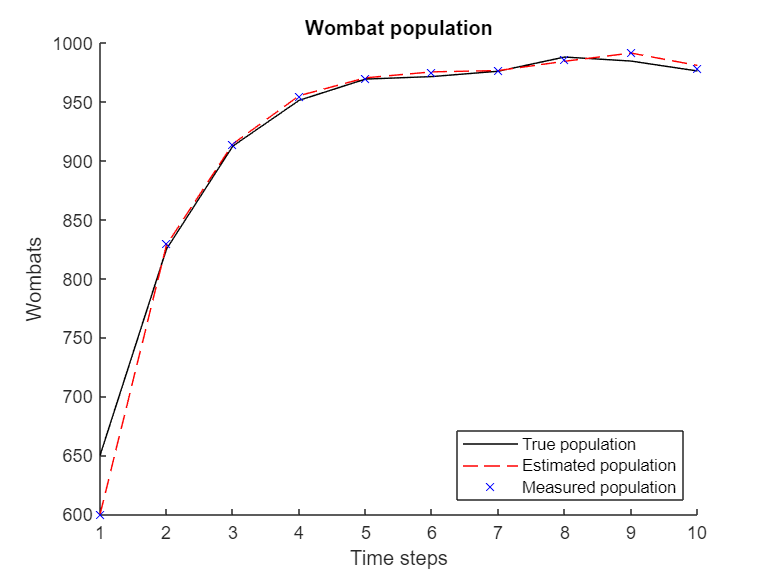

figure
hold on
plot(X_true(1, :), 'k-')
plot(X_est(1, :), 'r--')
plot(y, 'bx')
hold off
legend('True population', 'Estimated population', 'Measured population', 'Location','southeast');
title('Wombat population');
ylabel('Wombats');
xlabel('Time steps');

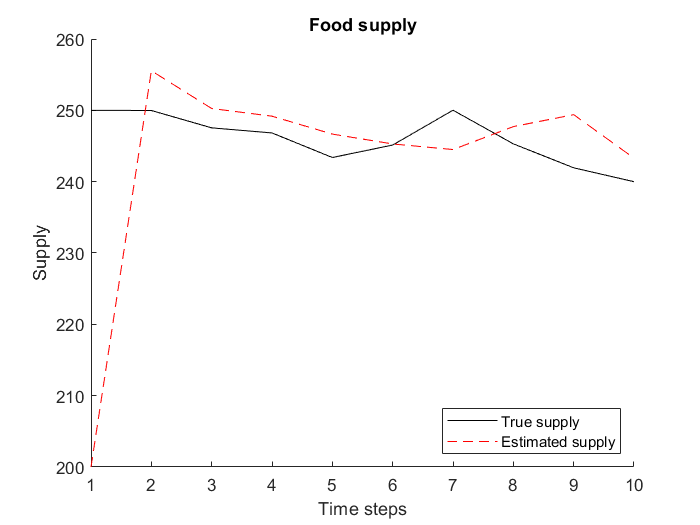


figure
hold on
plot(X_true(2, :), 'k-')
plot(X_est(2, :), 'r--')
hold off
legend('True supply', 'Estimated supply', 'Location','southeast');
title('Food supply');
ylabel('Supply');
xlabel('Time steps');

Let's also calculate the standard deviation of the state errors and plot it. It's common to plot the error with the error bounds to show whether the confidence levels assumed are correct. The error is assumed to be zero mean Gaussian so 99.7% of the values should be within 3 stds.

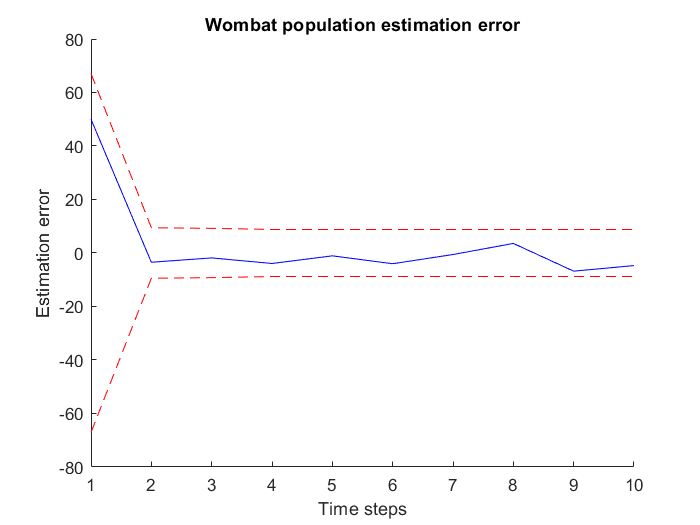

std_wombat = sqrt(P_store(1, :));
std_food = sqrt(P_store(4, :));

figure
hold on
plot(X_true(1, :) - X_est(1, :), 'b-')
plot(3*std_wombat, 'r--')
plot(-3*std_wombat, 'r--')
hold off
title('Wombat population estimation error');
ylabel('Estimation error');
xlabel('Time steps');

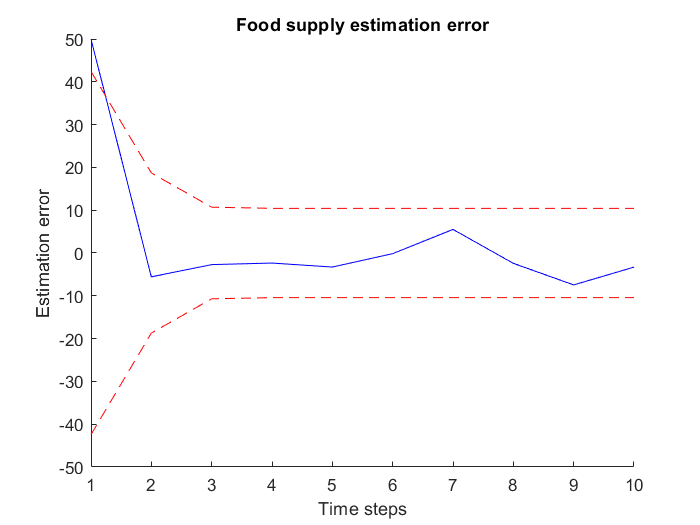


figure
hold on
plot(X_true(2, :) - X_est(2, :), 'b-')
plot(3*std_food, 'r--')
plot(-3*std_food, 'r--')
hold off
title('Food supply estimation error');
ylabel('Estimation error');
xlabel('Time steps');

As you can see from the results, while the initial error is large, the filter quickly converges and is able to track the true state. Moreover, as expected, the standard deviation is quickly reduced.